# Character Recognition

clear all
clc
% There are 55 images of 0-9, A-Z, a-z handwritten images
files = imageDatastore(strcat('D:\Lakshay\M.Tech\Sem 1\EE608_Digital Image Processing\DIP Project\7_Best_62Classes\Img'), "FileExtensions",'.png').Files;
nFiles = size(files)    % we require just 55 * (10 + 26) = 1980 files from this readed files

nFiles =         3410           1


## Digits

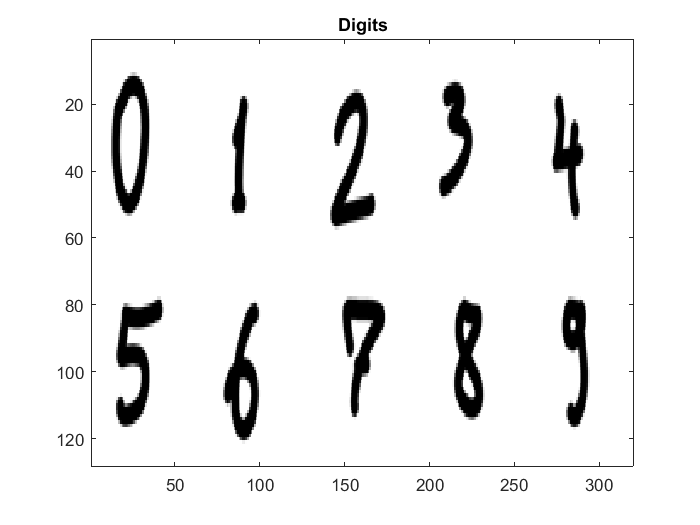

digits = zeros(64*64, 10);
for i = 1:10
    img = im2gray(imread(files{55*(i-1)+1}));
    imgSmall = imresize(img, [64 64]);  % Resizing the image to small size
    [row, col]= size(imgSmall);
    digits(:, i) = reshape(imgSmall, row*col , 1);
end

imgClusDigit = zeros(64*2, 64*5);  % 2*5 grid of images
FT_img_Digit = zeros(64*2, 64*5);
for i = 1:2
    for j = 1:5
        n = 5*(i-1) + j;    % 5 for the number of column
        imgClusDigit(1+(i-1)*64:i*64, 1+(j-1)*64:j*64) = reshape(digits(:, n), 64, 64);
        
        %% For Fourier Transform of Image
        ftimg = fft2(reshape(digits(:, n), 64, 64));
        ftimg_ = abs(ftimg)*255/max(max(abs(ftimg)));
%         figure; imshow(fftshift(ftimg_))
        FT_img_Digit(1+(i-1)*64:i*64, 1+(j-1)*64:j*64) = fftshift(ftimg_);
    end
end
figure; imagesc(imgClusDigit), colormap gray, title("Digits")

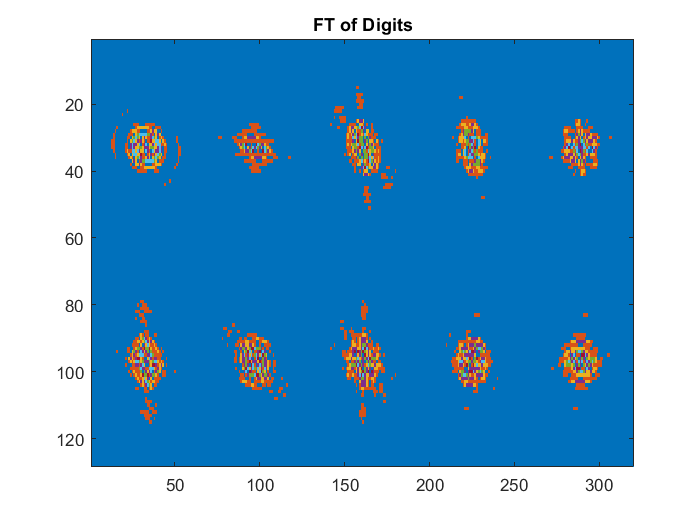

figure; imagesc(FT_img_Digit), colormap lines, title("FT of Digits")

## Alphabets

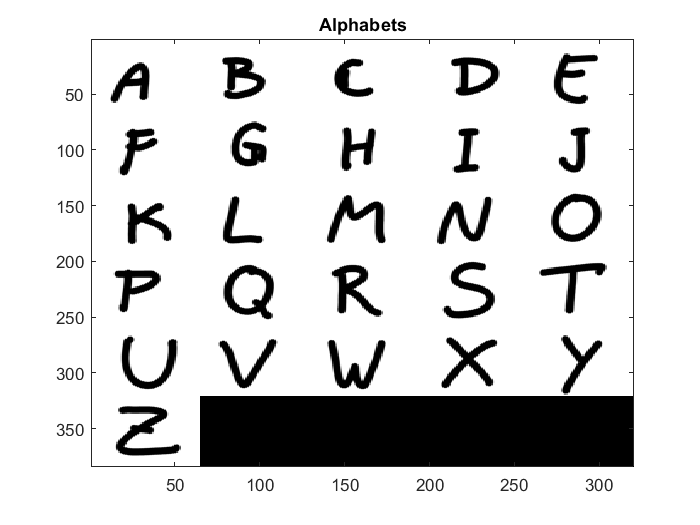

alphabets = zeros(64*64, 30);
for i = 11:36   % From 11 as 10 are for digits
    img = im2gray(imread(files{55*(i-1)+1}));
    imgSmall = imresize(img, [64 64]);  % Resizing the image to small size
    [row, col]= size(imgSmall);
    alphabets(:, i-10) = reshape(imgSmall, row*col , 1);
end

%% For output as the cluster images
imgClusAlp = zeros(64*6, 64*5);  % 6*5 grid of images
FT_img_Alphabets = zeros(64*6, 64*5);
for i = 1:6
    for j = 1:5
        n = 5*(i-1) + j;    % 5 for the number of column
        imgClusAlp(1+(i-1)*64:i*64, 1+(j-1)*64:j*64) = reshape(alphabets(:, n), 64, 64);
    
        %% For Fourier Transform of Image
        ftimg = fft2(reshape(alphabets(:, n), 64, 64));
        ftimg_ = abs(ftimg)*255/max(max(abs(ftimg)));
%         figure; imshow(fftshift(ftimg_))
        FT_img_Alphabets(1+(i-1)*64:i*64, 1+(j-1)*64:j*64) = fftshift(ftimg_);
    end
end
figure; imagesc(imgClusAlp), colormap gray, title("Alphabets")

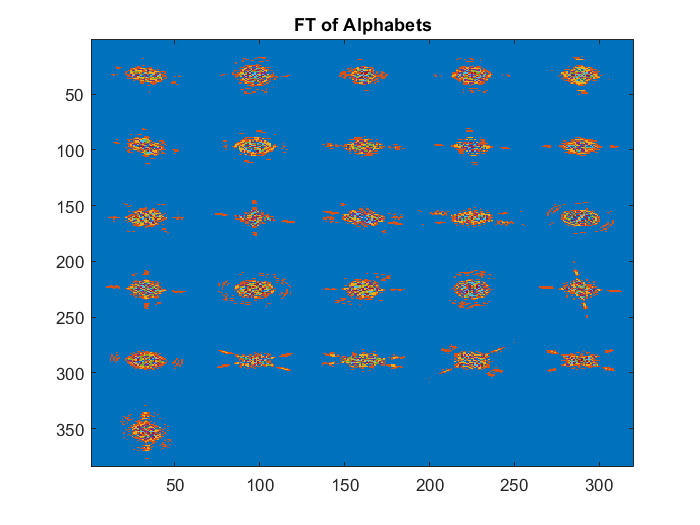

figure; imagesc(FT_img_Alphabets), colormap lines, title("FT of Alphabets")

## DataMatrix

%% It loads 4 matrix: 
% 1. train_imgMat - Tran Images in column vector  
% 2. train_img_FT_Mat - Tran Images Fourier Transform in column vector
% 3. test_imgMat, 
% 4. test_img_FT_Mat

load imgEdgeMatrix.mat  % Canny Edge of Images 

### Reading DataMatrix

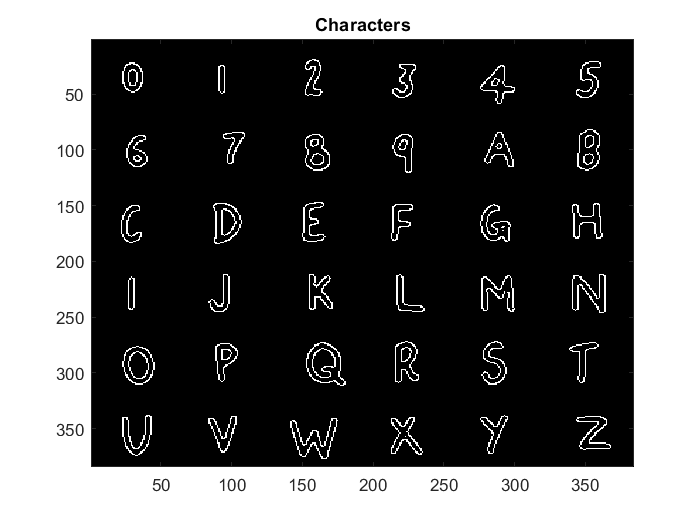

% Reading each char from datamatrix 
digAplha = zeros(64*64, 36);
digAplha_FT = zeros(64*64, 36);
for i = 1:36
    % As train set have 40 image of each character
    digAplha(:,i) = train_imgMat(:, 40*i);  
    digAplha_FT(:,i) = train_img_FT_Mat(:, 40*i);
end

% Now ploting the readed image in the grid form

digAplhaClus = zeros(64*6, 64*6);  % 6*6 grid of images of 0-9 & A-Z
digAplha_FT_Clus = zeros(64*6, 64*6);
for i = 1:6
    for j = 1:6
        n = 6*(i-1) + j;    % 6 for the number of column
        digAplhaClus(1+(i-1)*64:i*64, 1+(j-1)*64:j*64) = reshape(digAplha(:, n), 64, 64);
        digAplha_FT_Clus(1+(i-1)*64:i*64, 1+(j-1)*64:j*64) = reshape(digAplha_FT(:, n), 64, 64);
    end
end
figure; imagesc(digAplhaClus), colormap gray, title("Characters")

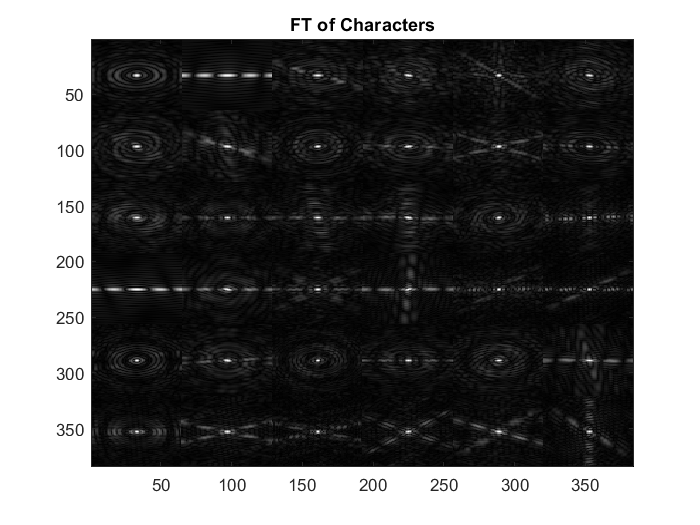

figure; imagesc(digAplha_FT_Clus), colormap gray, title("FT of Characters")

% % For individual reading the character form dataMatrix
% for i = 1:36
%     Img = reshape(train_imgMat(:, 40*i), row , col);    % As train set have 40 image of each character
% %     ftimg = fftshift(fft2(Img));
% %     figure; montage({Img, abs(ftimg)})
%     imgFt = reshape(train_img_FT_Mat(:, 40*i), row , col);
%     figure; montage({Img, imgFt})
% end

% charDict for keys 1-36  while values being 0-9 & A-Z
digit = 48:57;  % As ASCII code of zero is 48
alphabets = 'A':'Z';
keySet = 1:36;     % As there are 36 character in dataset
valueSet = ones(1, 36);
for i = 1:10
    valueSet(i) = digit(i);
end
for i = 11:36
    valueSet(i) = alphabets(i-10);
end

% Creating dictionary of characters
charDict = containers.Map(keySet,valueSet)

charDict =   Map with properties:

        Count: 36
      KeyType: double
    ValueType: double


% char(charDict(35))    % Will print the character representation

## Evaluating Model

% Predicting just on the basis of MSE of test image FT
% and the train image FT dataset
predTrue = 0;
szTestMat = size(test_img_FT_Mat);
ntestCol = szTestMat(2);

tImg_tobeDisp = 1:15:ntestCol   % As 15 test image available for each charcater

tImg_tobeDisp =      1    16    31    46    61    76    91   106   121   136   151   166   181   196   211   226   241   256   271   286   301   316   331   346   361   376   391   406   421   436   451   466   481   496   511   526


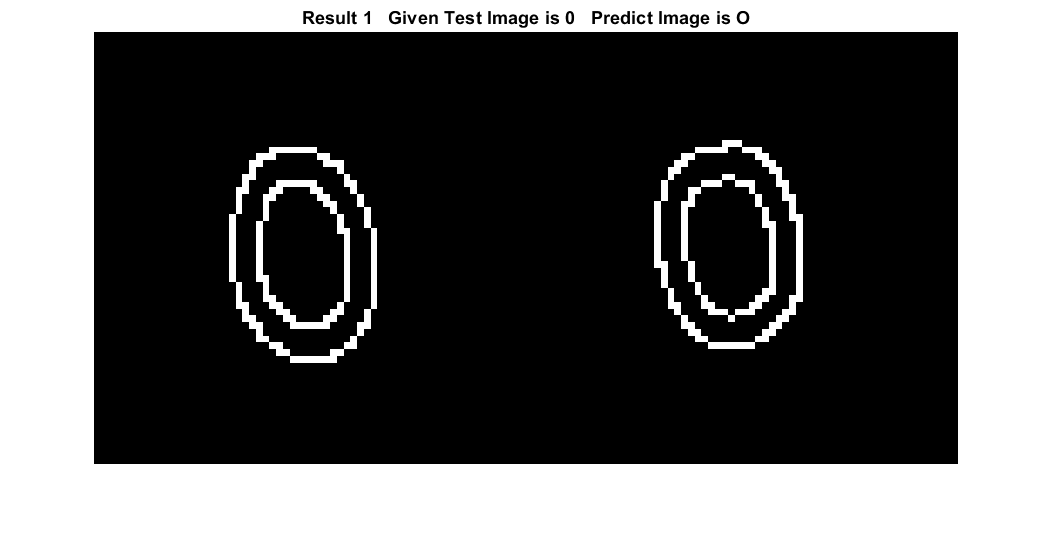

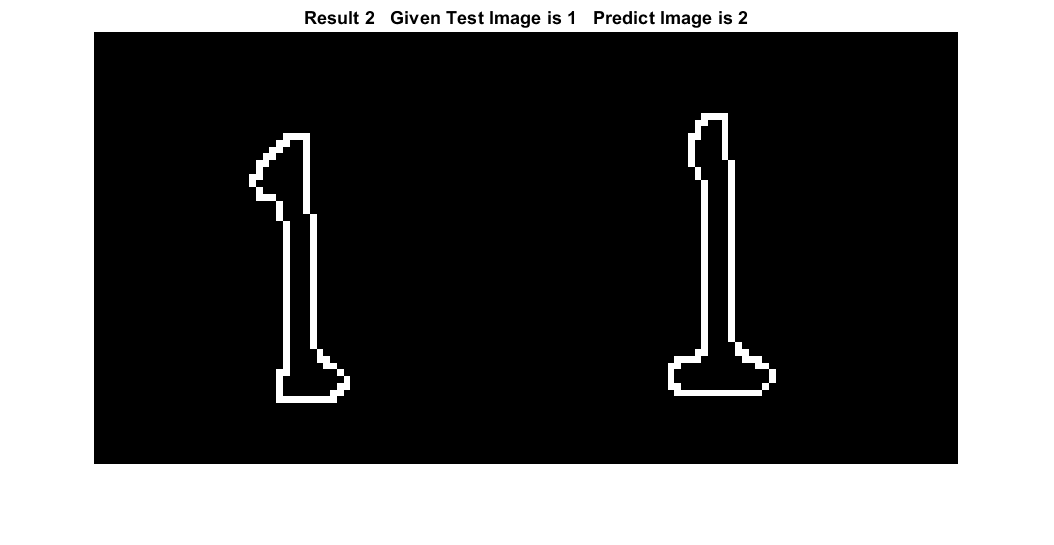

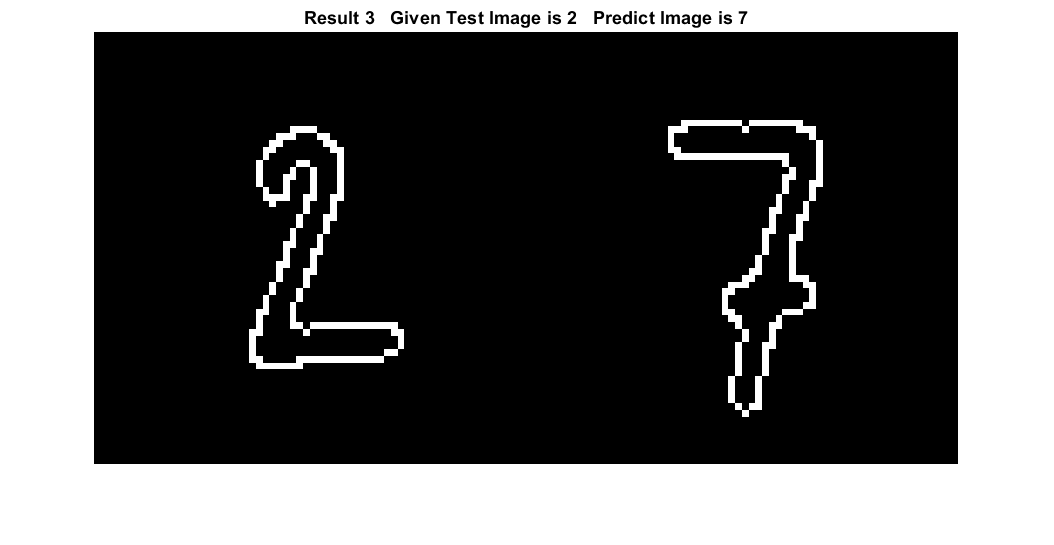

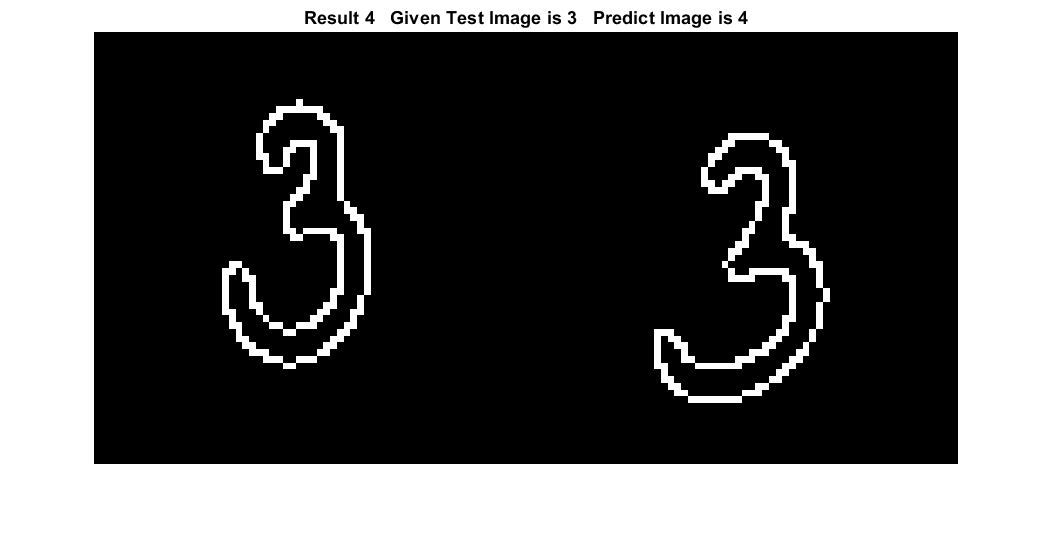

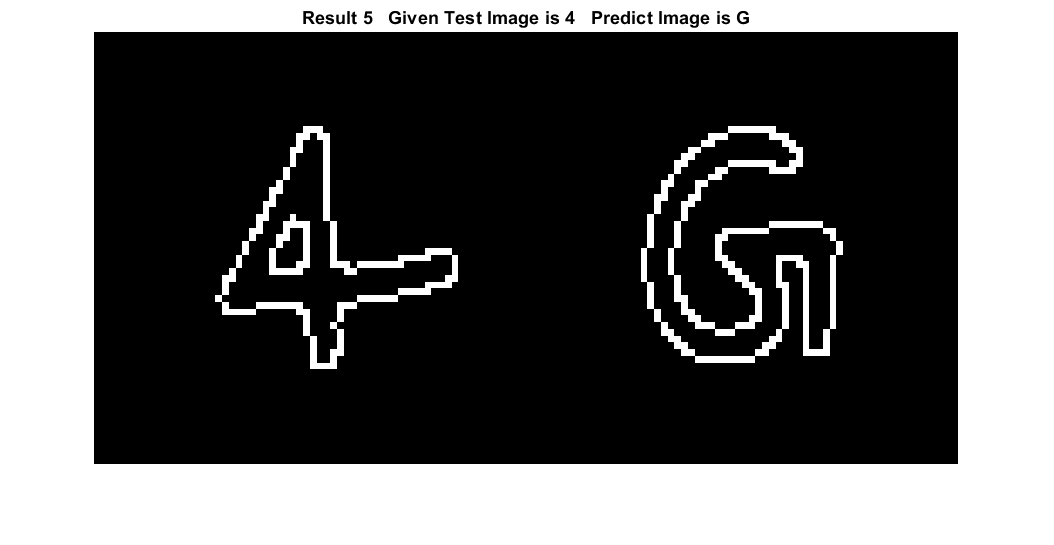

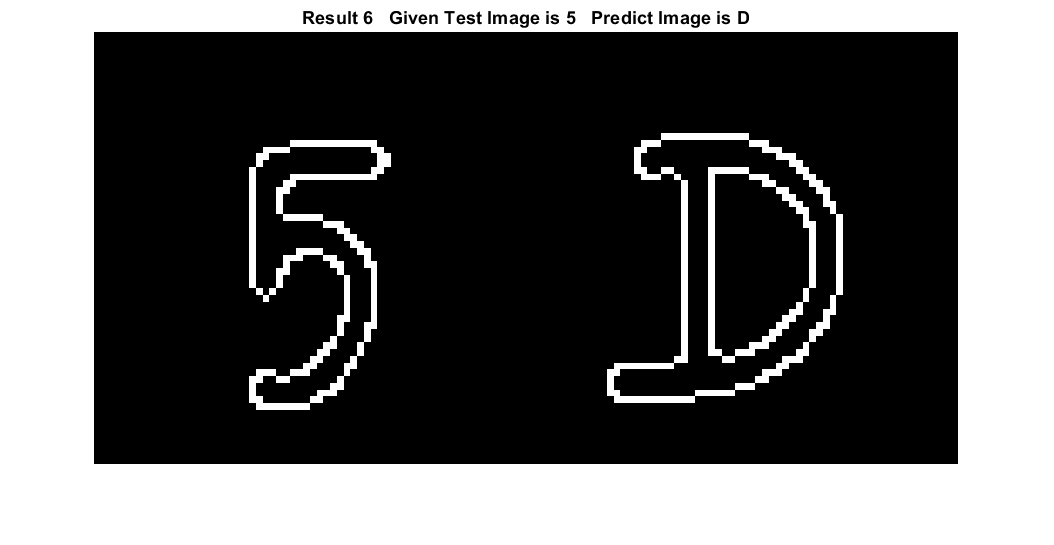

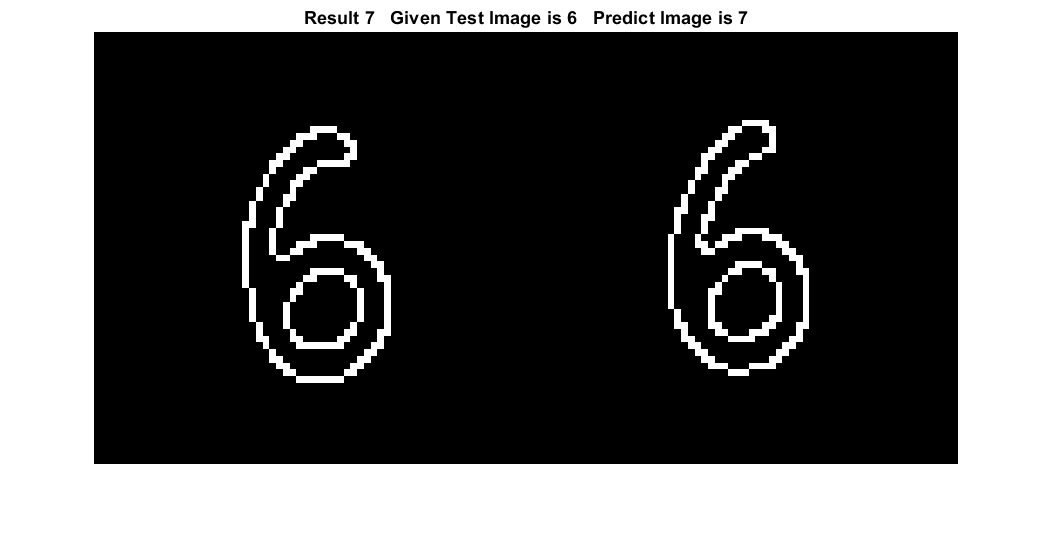

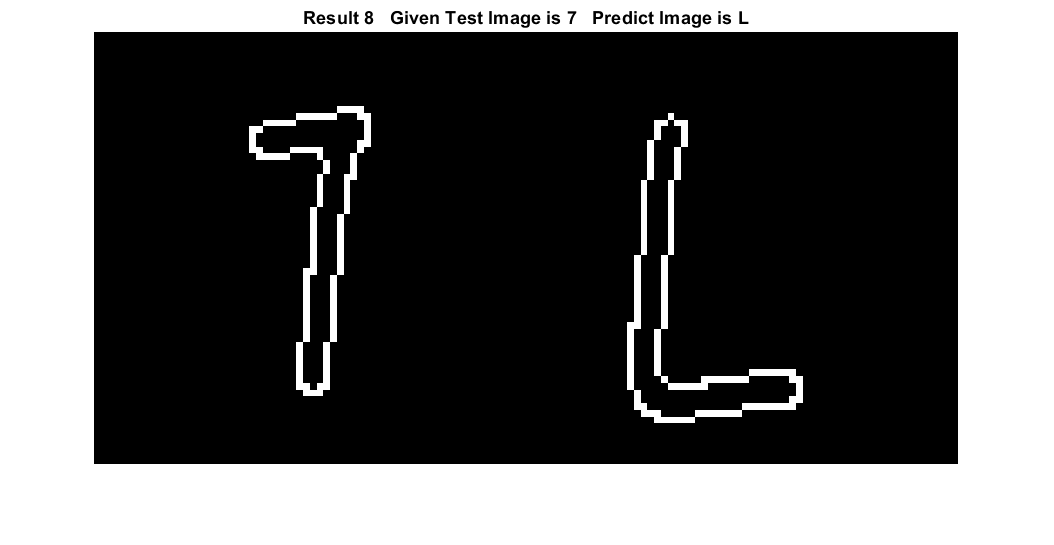

dispCnt = 1;
for i = 1:ntestCol
    testImg = test_img_FT_Mat(:, i);
    err = (train_img_FT_Mat - testImg).^2;  % Eucledian Distance
    err = sum(err, 1);  % Sum along colums
    % idx correspond to match found with column of train_img_FT_Mat
    [minErr ,idx] = min(err,[],'all', 'linear');
    
    k1 = int8(idx/40) + 1;   % As 40 train image available for each charcater
    k2 = int8(i/15) + 1;   % As 15 test image available for each charcater
    if k1 == 37
        k1 = 36;
    end
    if k2 == 37
        k2 = 36;
    end
    if k1 == k2
        predTrue = predTrue + 1;
    end
    
    %% Displaying some results
    if all(i == tImg_tobeDisp(dispCnt) && dispCnt <= 35)
        input = reshape(test_imgMat(:, i), 64, 64);
        predictImg = reshape(train_imgMat(:, idx), 64, 64);
        figure; montage({input, predictImg}), title("Result " + dispCnt + "   Given Test Image is " +char(charDict(k2)) + "   Predict Image is " +char(charDict(k1)))
        
%         input_FT = reshape(test_img_FT_Mat(:, i), 64, 64);
%         predictImg_FT = reshape(train_img_FT_Mat(:, idx), 64, 64);
%         figure; montage({input_FT, predictImg_FT}), colormap gray, title("There Fourier Transforms")
        dispCnt = dispCnt + 1;
    end
end

%% Calculating Accuracy of Model
totalTestImg = ntestCol;
accuracy = predTrue / ntestCol;
sprintf("We achives a accuracy of (in % ) ")

ans = "We achives a accuracy of (in "

disp(accuracy*100)

   29.2593



## Performing on self generated dataset

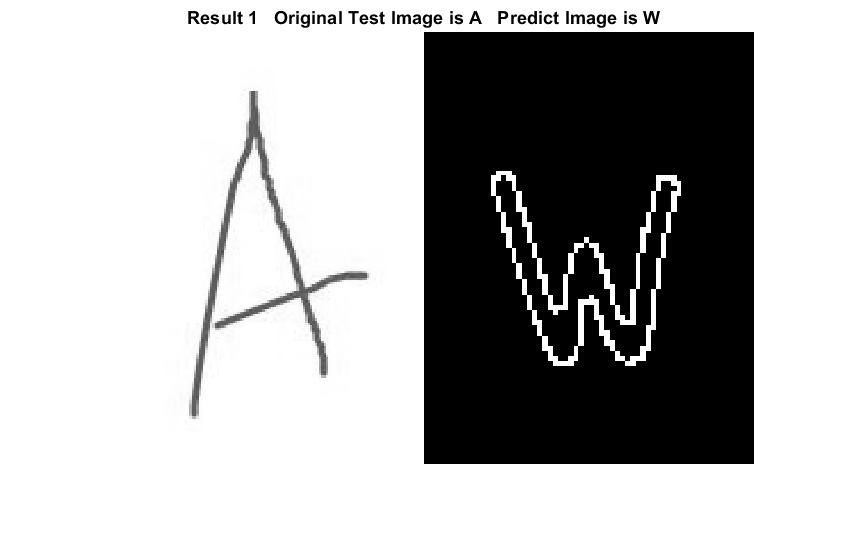

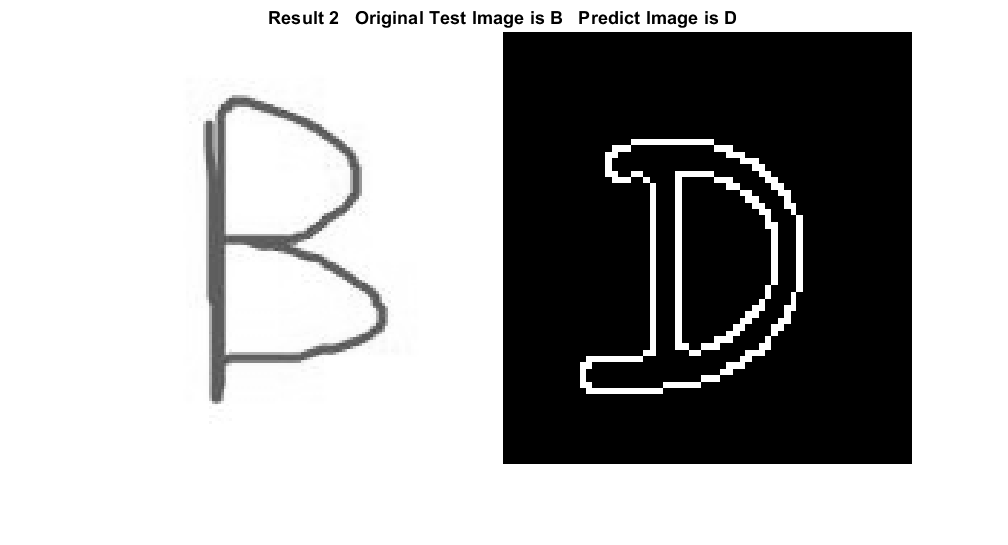

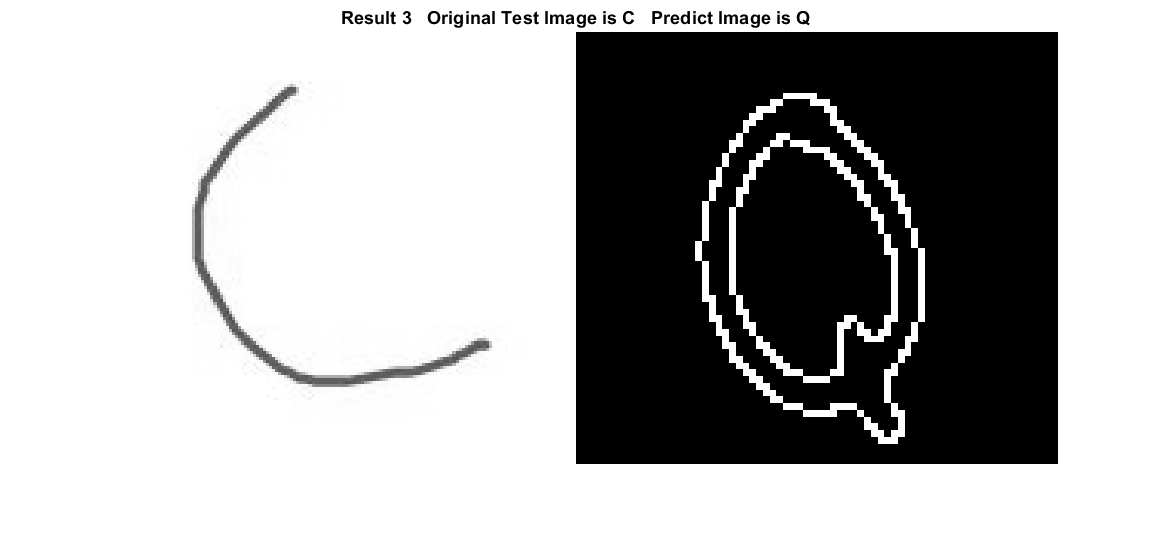

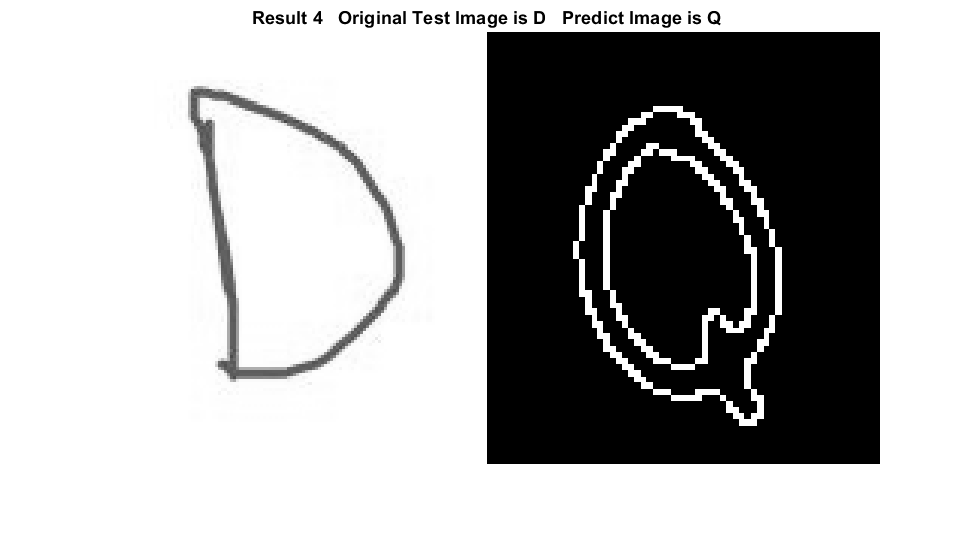

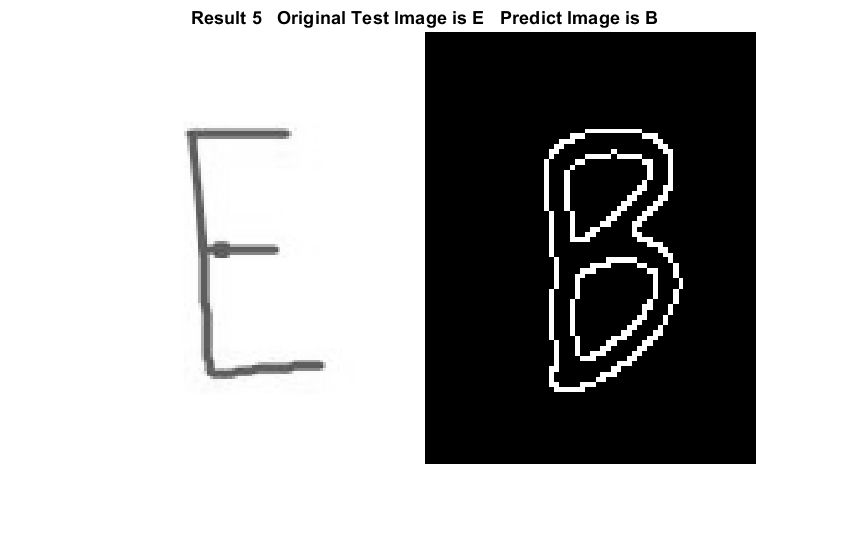

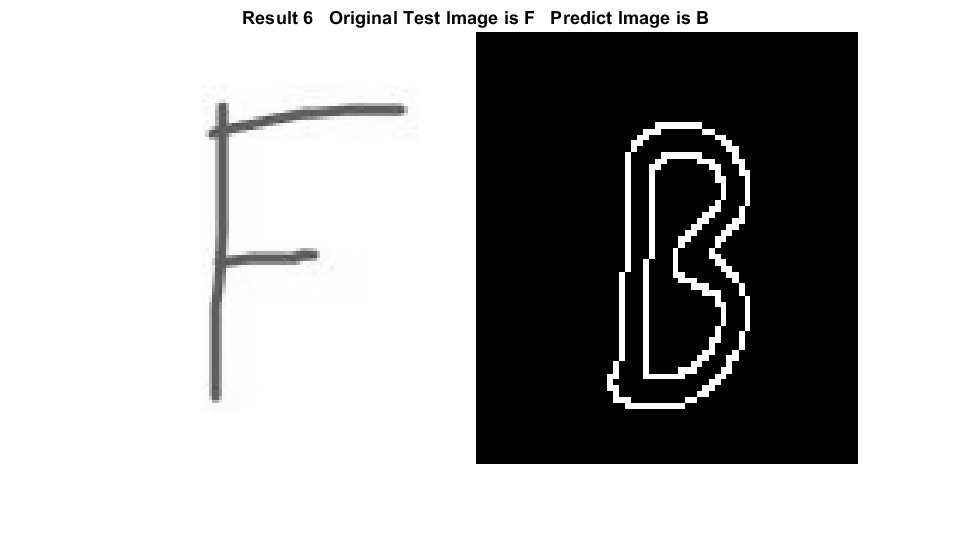

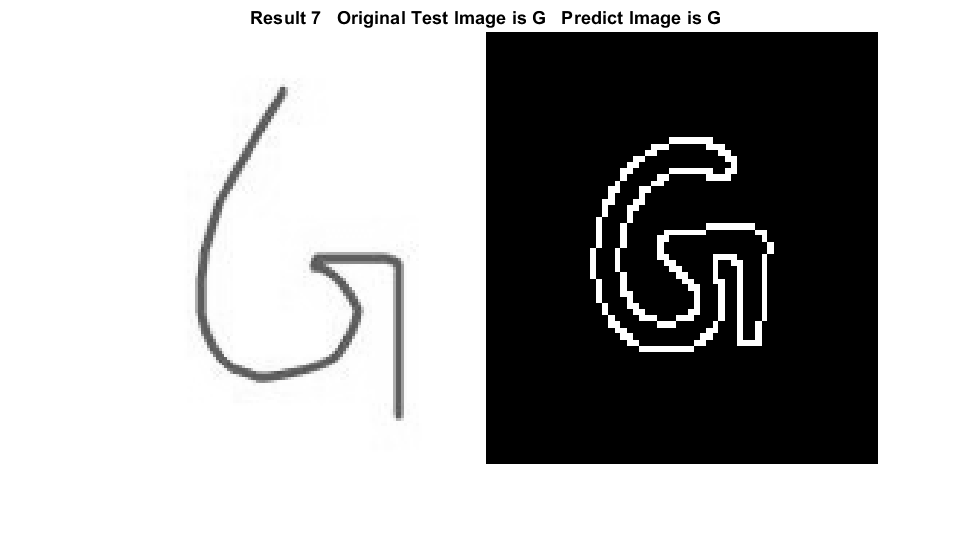

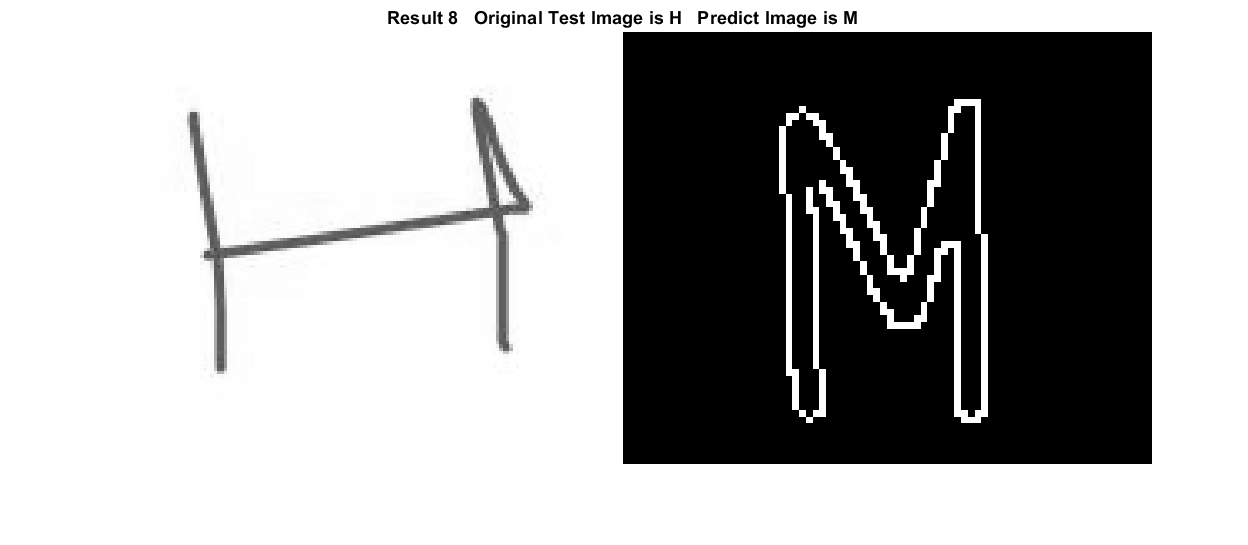

newFiles = imageDatastore(strcat('D:\Lakshay\M.Tech\Sem 1\EE608_Digital Image Processing\DIP Project\Test'), "FileExtensions",'.JPG').Files;
n_newFiles = size(newFiles);

for i = 1:n_newFiles(1)
    timg = im2gray(imread(newFiles{i}));
    tsmall = imresize(timg, [64 64]);
    tFil = medfilt2(tsmall);
    tedge = edge(tFil, "canny");
    ftimg = reshape(fftshift(fft2(tedge)), 64*64, 1);
    
    err = (train_img_FT_Mat - abs(ftimg)).^2;
    err = sum(err, 1);
    [minErr ,idx] = min(err,[],'all', 'linear');
    
    predictImg = reshape(train_imgMat(:, idx), 64, 64);
    predImgKey = int8(idx/40) + 1;
    if predImgKey == 37
        predImgKey = 36;
    end
    figure; montage({timg, predictImg}), title("Result " + i + "   Original Test Image is " +char(charDict(i+10)) + "   Predict Image is " +char(charDict(predImgKey)))
end

## Basics

% %% Loding images from folder
% temp = files{4}     % Files are cell array
% img = im2gray(imread(temp));
% imshow(img)
% im2 = imresize(img, [64 64]);
% imshow(im2)
% [row, col]= size(img)

% %% FT of Image 
% img = reshape(digits(:, 5), 64, 64);
% figure; imshow(img)
% ftimg = fft2(img);
% ftimg_ = abs(ftimg)*255/max(max(abs(ftimg)));
% figure; imshow(fftshift(ftimg_))

### Testing Try

% Predicting just on the basis of MSE of test image FT
% and the train image FT dataset
% Tidx = 330;     % Max num of col in testMat is 360- 10 for each character
% testImg = test_img_FT_Mat(:, Tidx);
% err = abs(train_img_FT_Mat - testImg);
% err = sum(err, 1)
% err'
% min(err)
% [minErr ,idx] = min(err,[],'all', 'linear');
% idx
% figure; imshow(reshape(test_imgMat(:, Tidx), 64, 64)), title("Actual Test Image")
% figure; imshow(reshape(train_imgMat(:, idx), 64, 64)), title("Predict")

% t = im2gray(imread("D:\Lakshay\M.Tech\Sem 1\EE608_Digital Image Processing\DIP Project\Test\C.JPG"));
% figure; imshow(t)
% tsmall = imresize(t, [64 64]);
% tFil = medfilt2(tsmall);
% tedge = edge(tFil, "canny");
% % imshow(tedge)
% ftimg = reshape(fftshift(fft2(tedge)), 64*64, 1);
% 
% err = abs(train_img_FT_Mat - abs(ftimg));
% err = sum(err, 1);
% % err'
% % min(err)
% [minErr ,idx] = min(err,[],'all', 'linear');
% figure; imshow(tedge), title("Input Image")
% figure; imshow(reshape(train_imgMat(:, idx), 64, 64)), title("Predict Image")